clc, clearvars;

defaultSimLocation = 'D:\Creo_Simulations';
currentDateTime = char(datetime('now', 'Format','yyyy_MM_dd__hh_mm'));

loadType = 'new';

switch loadType
    case 'new'
        [~,creoResultsLocation] = uigetfile_extended('xlsx', defaultSimLocation);

        % Get a list of all .xlsx files in the designated location
        fileList = dir(fullfile(creoResultsLocation, '*.xlsx'));
        fileNames = {fileList.name}';

        % Names to remove
        namesToRemove = {''}; % Change these to the names you want to remove
        % Remove names matching the provided names
        filteredFileNames = setdiff(fileNames, namesToRemove);
        % Create a struct with fields as filenames' last characters after '_' without file extension
        S = struct();
        for i = 1:length(filteredFileNames)
            [~, name, ~] = fileparts(filteredFileNames{i});
            splittedFileName = split(name, '_');
            filedName = splittedFileName{end}; % Get the last character after '_'
            S.(filedName) = readtable(fullfile(creoResultsLocation, filteredFileNames{i}));
        end
        
        matFileName_ = split(creoResultsLocation, '\');
        matFileName = [matFileName_{end-1} '_' currentDateTime '.mat'];
        save(matFileName, 'S');
        sprintf('File %s was saved...', matFileName)
    case 'load'
        dirRes = dir('*.mat');
        if isempty(dirRes)
            error('No .mat files found.');
        end
        fileNames = {dirRes.name};

        [idx, ok] = listdlg( ...
            'PromptString', 'Select a MAT file:', ...
            'SelectionMode', 'single', ...
            'ListString', fileNames);

        selectedFile = fileNames{idx};
        disp(['Selected file: ', selectedFile]);
        load(selectedFile);
end

ans = 'File STERLING_COOLING_2026_01_28__05_02.mat was saved...'

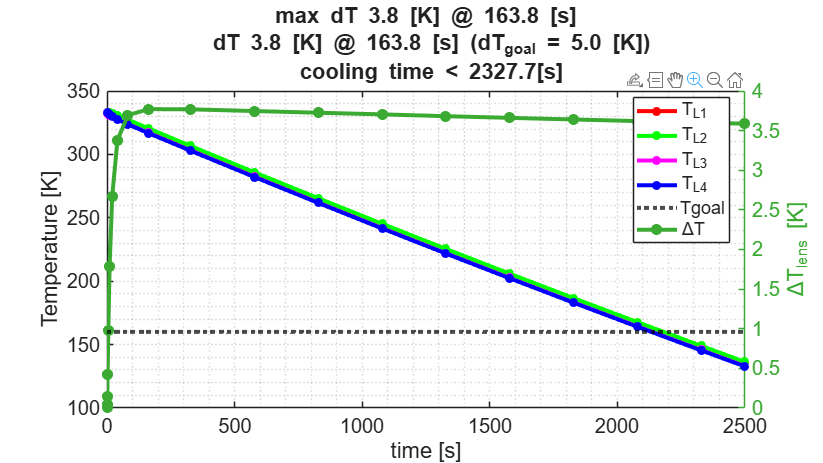

dTgoal = 5.0; % Max. gradient to consider image good
Tgoal = 160; % Min. temperature to consider optics cooled

t = S.L1.Seconds;
T1 = S.L1.K;
T2 = S.L2.K;
T3 = S.L3.K;
T4 = S.L4.K;

dT_lens = max([T1,T2,T3,T4], [], 2) - min([T1,T2,T3,T4], [], 2);

[dT_lens_max, indx_dTmax] = max(abs(dT_lens));
t_dT_lens_max = t(indx_dTmax);

indx_tFinal = find(dT_lens(indx_dTmax:end) < dTgoal, 1, 'first') + indx_dTmax - 1; % first absolute index allways true
tFinal = t(indx_tFinal);

dT_lens_end = abs(dT_lens(indx_tFinal));

indx1 = find(T1 < Tgoal, 1, 'first');
indx2 = find(T2 < Tgoal, 1, 'first');
indx3 = find(T3 < Tgoal, 1, 'first');
indx4 = find(T4 < Tgoal, 1, 'first');

tCooling = t(max([indx1, indx2, indx3, indx4]));

figure('Units','normalized', 'Position',[0 0 0.85 0.85])
% yyaxis left
plot(t,  T1,'r-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',20.0,...
    'DisplayName','T_{L1}'); hold on;
plot(t, T2,'g-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',20.0,...
    'DisplayName','T_{L2}');
plot(t, T3,'m-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',20.0,...
    'DisplayName','T_{L3}');
plot(t, T4,'b-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',20.0,...
    'DisplayName','T_{L4}');
yline(Tgoal, 'k:', 'LineWidth', 3.0, 'DisplayName','Tgoal')
ylabel('Temperature [K]');
xlabel('time [s]');
% xlim([0.1 tFinal])
legend('show', 'Location','best');
title(sprintf('max dT %.1f [K] @ %.1f [s]\n dT %.1f [K] @ %.1f [s] (dT_{goal} = %.1f [K])\n cooling time < %.1f[s]',...
dT_lens_max, t_dT_lens_max, dT_lens_end,  tFinal, dTgoal, tCooling));
set(gca, 'FontSize', 15);

yyaxis right
plot(t, dT_lens,...
    '-' , 'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0, 'DisplayName','\DeltaT');

ylabel('\DeltaT_{lens} [K]', 'Interpreter','tex');
grid minor

tMin = 0.1;
coolingPower_W = S.EXPC.mW/1000;

Unrecognized field name "EXPC".

totalEnergy_J = cumtrapz(t, coolingPower_W); %[mJ ---> J]
maxCoolPower = max(coolingPower_W(t > tMin));

figure('Units','normalized', 'Position',[0 0 0.85 0.85])

yyaxis left
semilogx(t, coolingPower_W,'-o' ,'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0);
ylabel('Cooling Power [W]');
xlabel('time [s]');
title(sprintf('max cooling Power %.f [W]\n total absorbed Energy %.f [J]', maxCoolPower, totalEnergy_J(end)));
set(gca, 'FontSize', 15);
xlim([tMin tFinal])
grid minor
yyaxis right
xlim([tMin t(end)])
semilogx(t, totalEnergy_J,'-o' ,'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0);
ylabel('Absorbed Energy [J]');
xlim([tMin tFinal])